## Задача 1

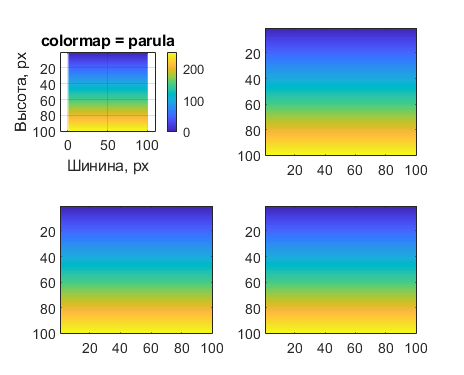

N = 100;

A1 = uint8(zeros(N));

for i = 1 : N
    for j = 1 : N
        A1(i,j) = 255 / N * i;
    end
end

A2 = A1;
A3 = A1;
A4 = A1;

f1 = figure('Position', [50, 50, 1050, 850]);

ax1 = subplot(2,2,1);
image(A1)
axis('equal')
grid on
colormap(ax1, 'parula');
colorbar
title('colormap = parula')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,2);
image(A2)

subplot(2,2,3);
image(A3)

subplot(2,2,4);
image(A4)

saveas(f1, 'e1.png')

## Задача 2

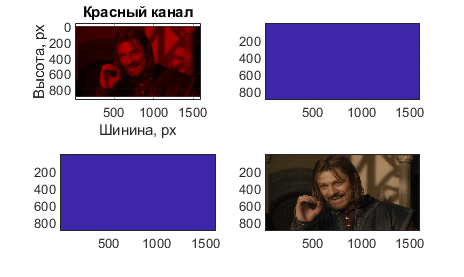

mem = imread('nelzya_mem.jpg');
black = uint8(zeros(size(mem(:,:,1))));

red = cat(3, mem(:,:,1), black, black);

f2 = figure('Position', [50, 50, 1250, 750]);

subplot(2,2,1)
image(red)
axis('equal')
grid on
title('Красный канал')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,2)
image(black)

subplot(2,2,3)
image(black)

subplot(2,2,4)
image(mem)

saveas(f2, 'e2.png')

## Задача 3

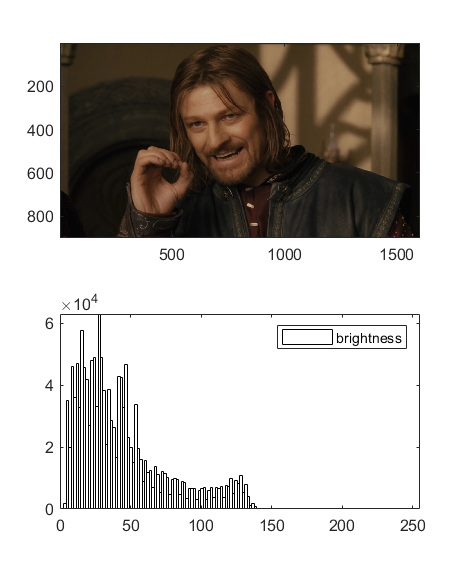

mem = imread('nelzya_mem.jpg');

brightness = uint8(mean(mem, 3));

f3 = figure('Position', [50, 50, 850, 1050]);

nBins = 100;

subplot(2,1,1)
image(mem);

subplot(2,1,2);
histogram(brightness, nBins, 'FaceColor', 'white')
legend('brightness')
xlim([0, 255])

saveas(f3, 'e3.png')